fs = 8000; % Sampling frequency

myVoice = audiorecorder(fs, 16, 1); % Create an audiorecorder object with the desired sampling frequency (fs), bit depth (16), and number of channels (1)

disp('Start speaking.')

Start speaking.


recordblocking(myVoice, 5) % Record your voice for 5 seconds

disp('End of recording. Playing back ...')

End of recording. Playing back ...


play(myVoice) % Playback the recorded voice

ans =   audioplayer with properties:

       SampleRate: 8000
    BitsPerSample: 16
      NumChannels: 1
         DeviceID: -1
    CurrentSample: 257
     TotalSamples: 40000
          Running: 'on'
         StartFcn: []
          StopFcn: []
         TimerFcn: []
      TimerPeriod: 0.0500
              Tag: ''
         UserData: []
             Type: 'audioplayer'


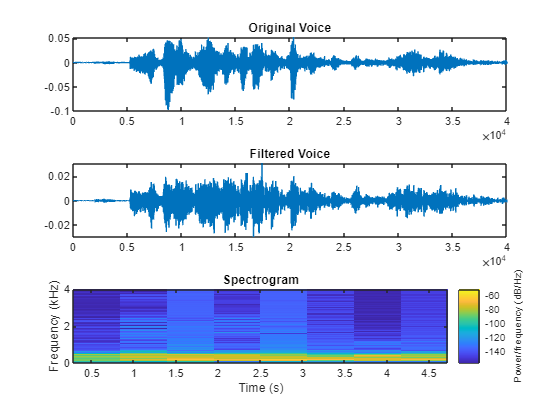


voice = getaudiodata(myVoice); % Get the recorded voice data

fcut1 = 200/(fs/2); % Lower cutoff frequency of 200Hz
fcut2 = 300/(fs/2); % Upper cutoff frequency of 300Hz
order = 50; % Filter order

d = designfilt('bandpassfir','FilterOrder',order,'CutoffFrequency1',fcut1,'CutoffFrequency2',fcut2); % Design the band-pass filter

output = filter(d,voice); % Apply the filter to the voice signal

%sound(output, fs) % Play the filtered voice signal

figure
subplot(3,1,1)
plot(voice) % Plot the original voice signal
title('Original Voice')
subplot(3,1,2)
plot(output) % Plot the filtered voice signal
title('Filtered Voice')
subplot(3,1,3)
spectrogram(output,[],[],[],fs,'yaxis') % Plot the spectrogram of the filtered voice
title('Spectrogram')